# Simple Areal-tp-point exemple with synthetic data.

## Référance:

Kyriakidis, P. C., & Yoo, E. H. (2005). Geostatistical prediction and simulation of point values from areal data. *Geographical Analysis*, *37*(2), 124–151. https://doi.org/10.1111/j.1538-4632.2005.00633.x

clc; % clear the command line
addpath(genpath('./.'));  % Add folder and sub-folder to path
dbstop if error  % activate debug in error

Define the synthetic case study

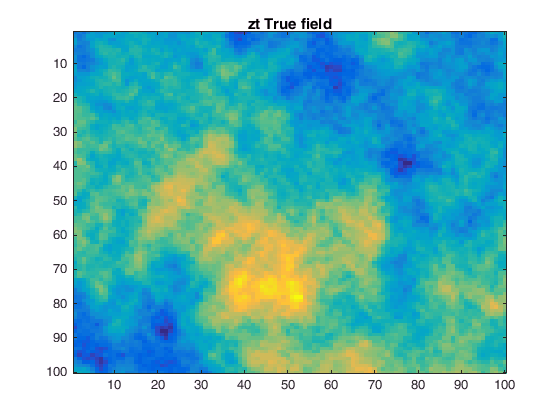

covar.model='exponential'; covar.range0=[20 20]; covar.c0=1;covar.azimuth=0;
gen.covar= kriginginitiaite(covar);
grid_gen.x=1:100;
grid_gen.y=1:100;
[grid_gen.X,grid_gen.Y] = meshgrid(grid_gen.x, grid_gen.y);
grid_gen.nxy =numel(grid_gen.X);
grid_gen.nx=numel(grid_gen.x);
grid_gen.ny=numel(grid_gen.y);
zt = fftma_perso(gen.covar, grid_gen);
NSigma.dx=5;
NSigma.dy=5;
NSigma.x = NSigma.dx/2:NSigma.dx:grid_gen.x(end);
NSigma.y = NSigma.dy/2:NSigma.dy:grid_gen.y(end);
[NSigma.X,NSigma.Y] = meshgrid(NSigma.x, NSigma.y);

c_axis=[ min(zt(:)) max(zt(:))];
imagesc(grid_gen.x, grid_gen.y, zt); caxis(c_axis); title('zt True field');

Built the matrix G which link the true variable zt to the measured coarse scale d

G = zeros(numel(NSigma.X),grid_gen.nxy);
for ij=1:grid_gen.nxy
     [~,id_z]=min((grid_gen.X(ij)-NSigma.X(:)).^2 + (grid_gen.Y(ij)-NSigma.Y(:)).^2);
     G(id_z,ij)=1;%/(NSigma.dx*NSigma.dy);
end
for ij = 1:numel(NSigma.X)
    G(ij,G(ij,:)==1) = 1 ./ sum(G(ij,:)==1);
end

Compute coarse scale d

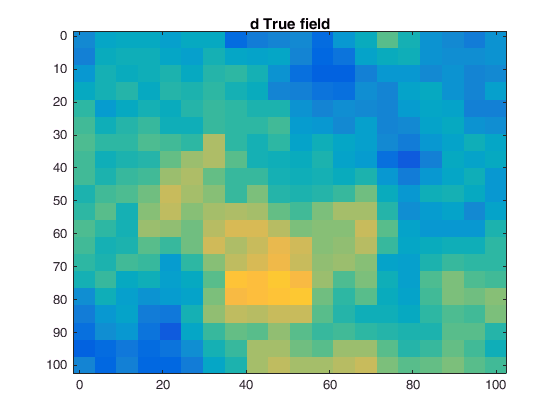

d = reshape(G * zt(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, d); caxis(c_axis); title('d Average of True field');

kriging prediction

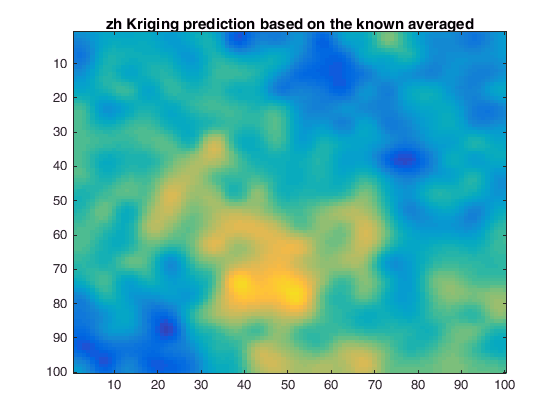

Cz = covardm_perso([grid_gen.X(:) grid_gen.Y(:)], [grid_gen.X(:) grid_gen.Y(:)], gen.covar);
Czd = Cz * G';
Cd = G * Czd;
W=zeros(grid_gen.nxy,numel(NSigma.X));
for ij=1:grid_gen.nxy
    W(ij,:) = Cd \ Czd(ij,:)';
end
zh = reshape( W * d(:), grid_gen.ny,grid_gen.nx);
imagesc(grid_gen.x, grid_gen.y, zh); caxis(c_axis); title('zh Kriging prediction based on d');

Build unconditional realization

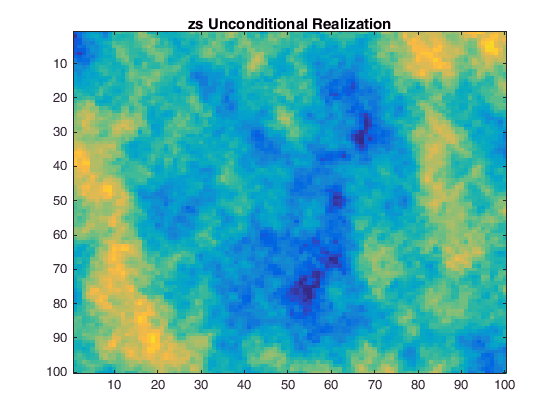

zs = fftma_perso(gen.covar, grid_gen);
imagesc(grid_gen.x, grid_gen.y, zs); caxis(c_axis); title('zs Unconditional Realization');

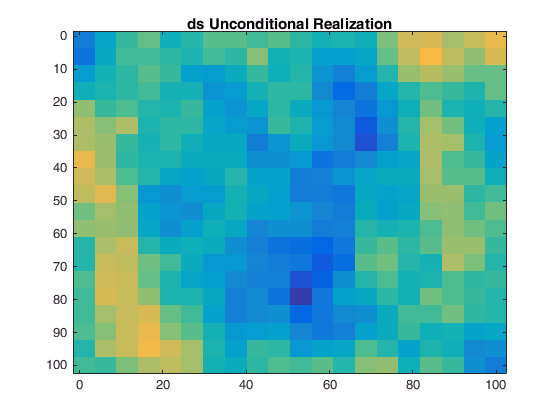

ds = reshape(G * zs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, ds); caxis(c_axis); title('ds Average of Unconditional Realization');

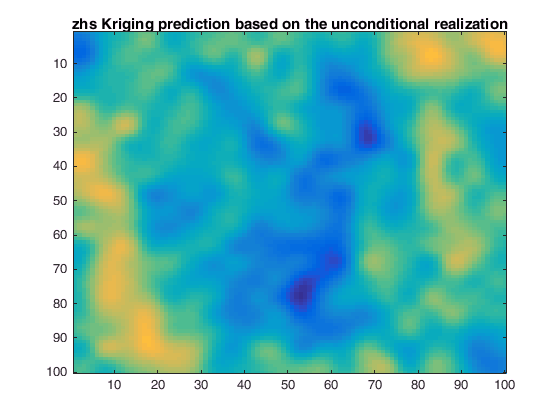

zhs = reshape( W * ds(:), grid_gen.ny,grid_gen.nx);
imagesc(grid_gen.x, grid_gen.y, zhs); caxis(c_axis); title('zhs Kriging prediction based on ds');

Build condtional realization

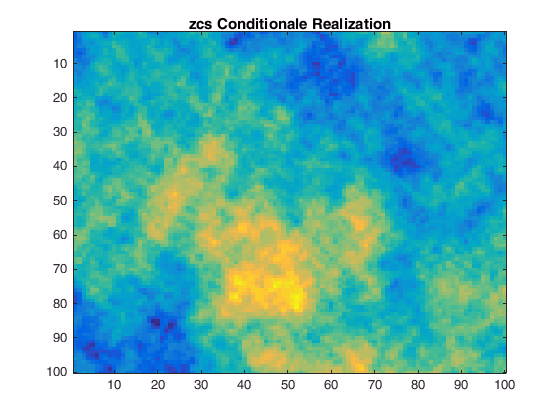

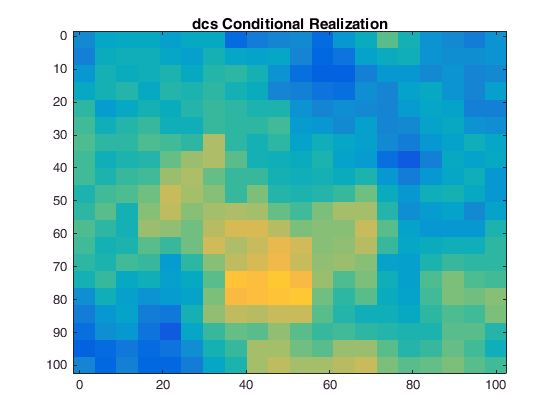

zcs = zh + (zs - zhs);
imagesc(grid_gen.x, grid_gen.y, zcs); caxis(c_axis); title('zcs Conditionale Realization');
dcs = reshape(G * zcs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, dcs); caxis(c_axis); title('dcs Average of Conditional Realization');